Francisco Moyet Vargas

2/1/2022

CE 536

Assignment 1

**Exercise 1:**

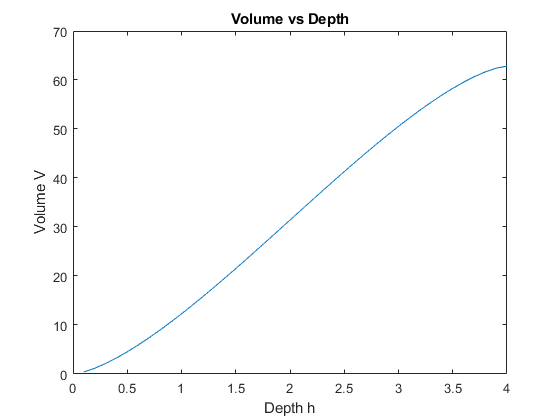

r = 2; % radius of hollow horizontal cylinder
L = 5; % length of cylinder
h = 0.1:0.1:2*r; % vector of differents depth of the liquid in the cylinder
V = L*(r^2*acos((r-h)/r)-(r-h).*sqrt((2*r.*h)-h.^2));
figure(1)
plot(h,V) % plot(x,y) 
xlabel('Depth h');
ylabel('Volume V');
title('Volume vs Depth');

**Exercise 2: Forward Euler's Method.**

dt = 0.1; % step size
t = 0:dt:12; % seconds vector from 0 to 12, step size dt

g = 9.8; % gravity constant m/s^2
c = 0.25; % drag coefficient kg/m
m = 68.1;% weight of person kg
n = length(t);
v = zeros(1,n); % zeros(rows,columns), to create a space in memory
v(1)=0; % initial condition v( t(1) = 0) = 0

for i=1:n-1
    v(i+1)=v(i)+dt*(g-c/m*v(i)^2);
end

**Exercise 3: **

% Analytical solution
syms c(t); % create symbolic function c(t)
biomremediation_kinetics = diff(c,t) == -4*0.5*(c/(2+c));
condition1 = c(0) == 2;
solution1 = dsolve(biomremediation_kinetics,condition1);
biomremediation_kinetics

$$biomremediation\_kinetics(t) = \frac{\partial }{\partial t}c\left(t\right)=-\frac{2\,c\left(t\right)}{c\left(t\right)+2}$$

solution1 

$$solution1 = 2\,W_{0}\left(\frac{{\mathrm{e}}^{\log\left(2\right)-t+1}}{2}\right)$$

## Numerical Solution using Forward Euler%%

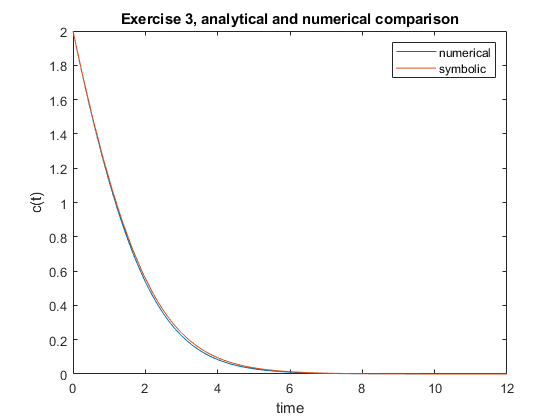

mu = 4; % maximum specific substrate utilization rate day^-1
k = 2; % Monod half saturation constant = 2 mg/L
X = 0.5; %biomass concentration = 0.5 mg/L
dt = 0.1; % increment in time 
t = 0:dt:12;
c = zeros(1,length(t));
n = length(t); % length of t
c(1) = 2 ;%c(0)==2, initial condition
for i = 1:n-1
c(i+1) = dt*-mu*X*c(i)/(k+c(i))+c(i);
end
figure(2)
plot(t,c)
xlim([0 12])
hold on
fplot(solution1)
legend('numerical','symbolic')
xlabel('time')
ylabel('c(t)')
title('Exercise 3, analytical and numerical comparison')

**Exercise 4.**

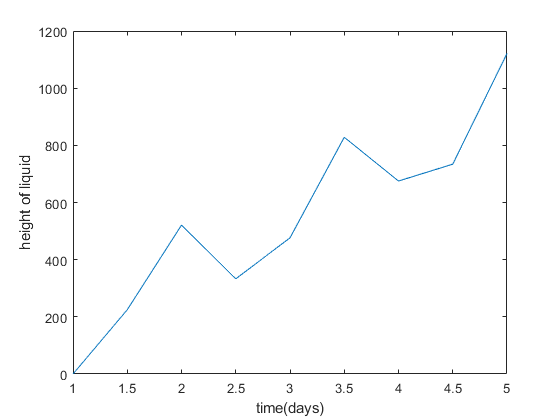

A = 1200; % surface area m^2
Q = 400; % constant flow rate m^3/day
dt = 0.5; % stepsize
t = 1:dt:5; % time 5 days
y = zeros(1,length(t)); % create vector y
y(1) = 0; % initial condition
n = length(t);
for i=1:n-1
    y(i+1)= 3*dt*Q*(sin(i))^2-Q*dt+y(i);
end
figure(3)
plot(t,y)
xlabel('time(days)')
ylabel('height of liquid')

**Exercise 5.**

% Create a matrix:
b=[50 0 160 0 0];b =b';
A =[6 0 -1 0 0;
    3 -3 0 0 0;
    0 -1 9 0 0;
    0 1 8 -11 2;
    3 1 0 0 -4];
rank(A);% 5 unknows and rank is 5, OK
% We have Ax = b then x = A\b
rank(A);
x = A\b;
for i = 1:5
fprintf("C%i = %g\n",i,x(i))
end

C1 = 11.5094
C2 = 11.5094
C3 = 19.0566
C4 = 16.9983
C5 = 11.5094


**Exercise 6:**

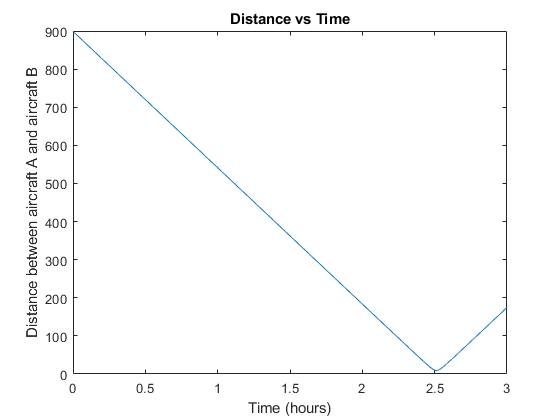

t = 0:0.00001:3; % time vector
d = sqrt((800-t*320).^2 +(410 - t*160).^2 ); % distance vector
[minimum,index] = min(d); 
figure(4)
 plot(t,d)
ylabel('Distance between aircraft A and aircraft B')
xlabel('Time (hours)')
title('Distance vs Time')

At approximetely t = 2.43477 the distance between aircrafts A and B is 29.2125

fun = @f; 
z = fzero(fun,2);
fun(z);

% this function was defined in a separate m file
% function y =f(x)
% y = sqrt((800-x*320)^2 +(410 - x*160)^2 ) - 30;
% end
fprintf('By using the fzero function, aircraft A and B are within 30 mi of each other when t = %g\n in hours.',z)

By using the fzero function, aircraft A and B are within 30 mi of each other when t = 2.43246
 in hours.

**Exercise 7(i)**

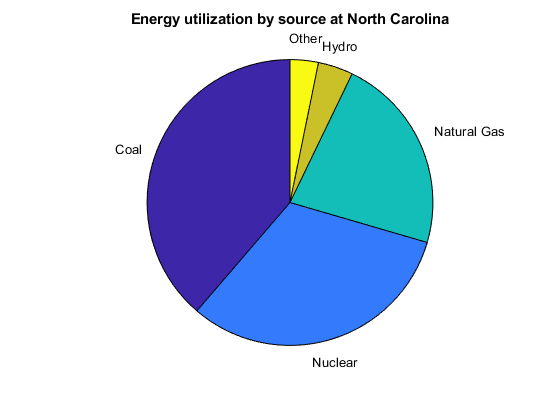

data1 = readcell("energy_generation_nc",'Range','A5:C10'); % reading file, truncated

nrows = size(data1,1); % number of rows in the file

labels = cell(nrows-1,1); % create array of n rows and 1 column
values = zeros(nrows-1,1)'; % column vector vector
for i=2:nrows
    labels{i-1,1}=data1{i,3}; % labels are cell arrays
    values(i-1) = data1{i,2};
end
figure(5)
pie(values,labels)
title('Energy utilization by source at North Carolina')

**Exercise 7(ii)**

data2 = readcell('energy_generation_all_states'); % readcell bc. alphanumerical data
state = input('Enter state abrevation\n','s'); % input command
statesnames = readcell('states.xlsx','Range','B:C');
m = size(statesnames,1); % 51 rows
for i=1:m % to know the state name
    if (strcmpi(statesnames{i,2},state)== true)
        state_name = statesnames{i,1}
        break     
    end
end

state_name = 'Alaska'

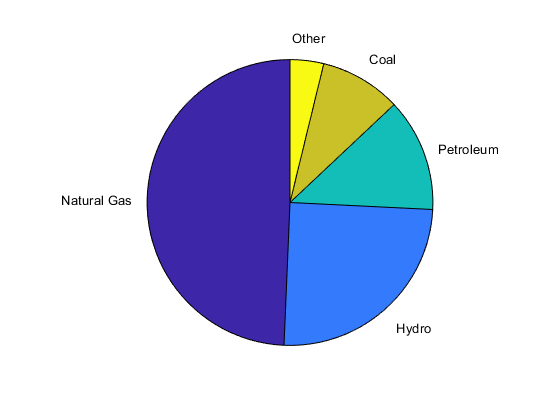

nrows2 = size(data2,1);
labels2 = cell(0,1); % empty cell array
values2 = zeros(0,1); % empty vector
k=0; 

for i = 1:nrows % verify each row of the sheet
    if (strcmpi(data2{i,1},state)==true)
        k = k+1;
        labels2{k,1} = data2{i,2};
        values2(k,1) = data2{i,3};
    end
end
figure(6)
pie(values2,labels2)